# Adding more complex constraints on a model 

## Authors: Thomas Pfau,Life Sciences Reasearch Unit, University of Luxembourg, Luxembourg.

## Reviewers: 

## INTRODUCTION

The COBRA Toolbox offers the possibility to add additional constraints to a model that are not direct flux constraints. One example is already indicated in the constraining models tutorial which introduces coupling constraints[1], but there are plenty of other possibilities that can be achieved using constraints.

The tools introduced in this tutorial are mainly aimed at developers who want to implement complex algorithms or formalism within the COBRA Toolbox environment, but the basics are also useful to integrate specific properties of a model or specific literature data. The section "The COBRA Model structure" is aimed at developers and can be skipped by users who don't to go into the details.

## The COBRA Model structure

In general, the COBRA toolbox represents a model in a struct using multiple fields to represent the different properties of the model. Of particular interest for analysis is the stoichiometric matrix S (which represents the metabolic stoichiometries of the reactions in the model). Under normal circumstances, this matrix can directly be translated into the linear problem matrix A of a problem struct as used by the Toolbox. However, since there are several algorithms which aim at manipulating reactions or metabolites, it is important to draw a distinction between the stoichiometric matrix S and any other constraints or variables which can be added to the model.

Therefore 3 additional matrices exist, where such information can be stored:

E - The matrix indicating the influence of additional variables on metabolite levels.

C - The matrix of additional constraints on the reactions, which are not derived from the steady state condition and

D - The matrix of interactions between additional Constraints and additional variables.

Overall A COBRA model will be translated into a Linear problem by combining these matrices in the following way:


$$LPproblem\ldotp A=\text{ }\left\lbrack \begin{array}{c}
model\ldotp S & model\ldotp E\\
model\ldotp C & model\ldotp D
\end{array}\right\rbrack$$
 

The Cobra toolbox allows one sided inequality constraints and equality constraints on a model. i.e. there is currently no mechanism to add a constraint like:


$$c_{low} \le v_{R1} \le c_{high}$$


directly. Instead it would be necessary to add the two constraints:


$$c_{low} \le v_{R1}$$


and


$$ v_{R1} \le c_{high}$$


which is commonly what solvers will translate these constraints into anyways. 

It is best practice to not manually alter the sizes of these matrices, but to use the appropriate model manipulation functions (addReaction/addMultipleReactions, addMetabolite/addMultipleMetabolites, addCOBRAVariables, addCOBRAConstraints). These functions will ensure, that the model structure stays in sync, and all necessary fields are updated appropriately. There is a convenience function to create the corresponding LPproblem struct to the given model: buildLPproblemFromModel(). This function will create and initialize all necessary fields and builds the corresponding LP problem. Any additional modifications of the LP problem imposed by an algorithm should be done on this LP and not on the original model structure.

## PROCEDURE

Initially, we will load a model that we want to modify by adding a few additional constraints. The model used will be the simple E.Coli core model:

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2018
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.7.4).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configur

model = getDistributedModel('ecoli_core_model.mat');
%Create a copy for comparisons
model_orig = model;

We will add a restriction on the activity of the two aconitase proteins present in E.Coli (aconA and aconB), which catalyse two steps in the citric acid cycle (see below)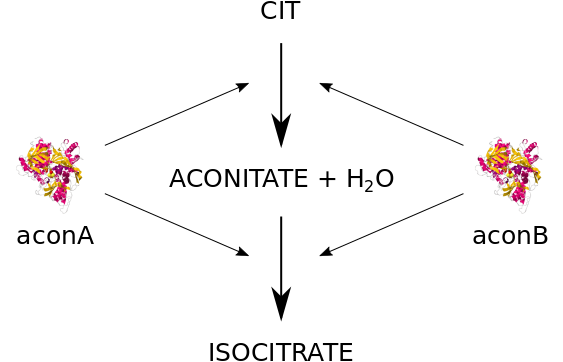

From UNIPROT[2], the Km value of aconitase acting on citrate is 6.13 and 23.8 umol/min/mg for aconA and aconB respectively. For cis-aconitate the values are 14.5 and 39.1 umol/min/mg, respectively. Since most models assume fluxes having the unit mmol/gDW/hr we will have to convert the units to mmol/hr instead of umol/min:

aconACit = 6.13 / 1000 * 60;
aconAAcon = 14.5 / 1000 * 60;
aconBCit = 23.8 / 1000 * 60;
aconBAcon = 39.1 / 1000 * 60;

From Wiśniewski and Rakus[3] the amount of aconA and aconB per mg E.Coli sample is ~4.05 pmol/mg and 95.95 pmol/mg respectively, with a weight of 97.676 kDa and 93.497 kDa, respectively.

aconAmol_per_g = 4.05 * 1000 * 1e-12;
aconBmol_per_g = 95.95 * 1000 * 1e-12;
aconA_molWeight = 97.676 * 1e3;
aconB_molWeight = 93.497 * 1e3;
aconAAmount = aconAmol_per_g * aconA_molWeight / 0.3; % divided by 0.3 to account for 
                                                      % the non water fraction assuming
                                                      % 70% water.
aconBAmount = aconBmol_per_g * aconB_molWeight / 0.3;

Now, there are two genes which code for aconitase in the ecoli core model: b0118 (aconB) and b1276 (aconA). Both the citrate hydratase and the aconitatde dehydratase have the same GPR rule: (b0118 or b1276), so they can both use either enzyme. 

aconAgene = 'b1276';
aconBgene = 'b0118';

We would like to add a constraint that not only restricts the activity of these two reactions, but also ensures that the turnover rates are considered. One mg of aconA can support a total flux of ~0.367 mmol/h of ACONTa

printRxnFormula(model,'rxnAbbrList',{'ACONTa'},'gprFlag', true);

ACONTa	cit[c] 	<=>	acon-C[c] + h2o[c] 	(b0118 or b1276)


OR .087 mmol/hr through ACONTb.

printRxnFormula(model,'rxnAbbrList',{'ACONTb'},'gprFlag', true);

ACONTb	acon-C[c] + h2o[c] 	<=>	icit[c] 	(b0118 or b1276)


However, it will not be able to do both at the same time. Therefore, we can assume that in addition to its normal metabolites, the reaction also consumes some of the enzyme (for this time step). However, both reactions can also be catalysed by aconB, so they might actually not use any of aconA. Therefore, we need additional constraints that represent the activity through these two reactions. In addition, we need variables that represent the efficiency of one mg of protein to catalyse the reactions.

Essentially, we have to encode:

A: The availability of the given proteins 

B: The efficiency of a protein to catalyse a specific reaction

C: The usage of that protein by the respective reaction.

And we will do so in this tutorial

## Adding availability variables.

The rxns field is intended to only represent reactions from the model, so if an additional variable is required for a specific task, this variable should not be generated in the rxns field, but in a distinct field for this kind of variables. Therefore, we will add availability variables, which can be thought of as exchange reaction for the enzymes. To do so, we use the following function

%addCOBRAVariables(model, idList, varargin)

The function takes an existing model, and a set of variable ids (**idList**) and generates all required fields for these variables. You can modify the properties of the variables by the following parameters which can either be supplied as parameter/value pairs:

addCOBRAVariables(model,{'newVar'},'lb', -5,'ub',3);

 or as a parameter struct:

params = struct();
params.lb = -5;
params.ub = 3;
addCOBRAVariables(model,{'newVar'},params);

The available parameters are:

- **'lb'** - The lower bound(s) of the variable(s) (default: -1000)

- **'ub'** - The upper bound(s) of the variable(s) (default: 1000)

- **'c'** - The objective coefficient(s) of the variable(s) (default: 0)

- **'Names'** - Descriptive name(s) of the variable(s) (default: idList)

We will now add the variables 'aconA' and 'aconB' with lower bounds 0 and upper bounds according to the values determined above.

aconVars = {'aconA','aconB'};
model = addCOBRAVariables(model,aconVars,'lb',[0;0],'ub',[aconAAmount;aconBAmount]);

We further need a conversion between the used amount of aconA and the potential flux through ACONTa. We also need this for ACONTb and the same for aconB.

linkedReactions = {'ACONTa','ACONTb'};
for enzyme = 1:numel(aconVars)
    for linkedReaction = 1:numel(linkedReactions)
        model = addCOBRAVariables(model,{strcat(aconVars{enzyme},'to',linkedReactions{linkedReaction})},'lb',0);
    end
end


## Adding usage efficiencies

Now, we can add the respective constraints.

To do so, we will use the function 

%addCOBRAConstraints(model, idList, d, varargin)

This function will add constraints to the given **model** using a list of reactions (**idList**) involved in the constraint and right hand side values for each constraint (**d**). By default, the constraint is assumed to be a limiting constraint, and the coefficients of the reactions is assumed to be one. 

i.e. if you run

constMod = addCOBRAConstraints(model,{'FBP','FBA'}, 5);

The added constraint will restrict the sum of flow through 'FBP' and 'FBA' to 5. The function has parameters which can be used either by parameter/value pairs:

constMod = addCOBRAConstraints(model,{'FBP','FBA'}, 5, 'c',[0.2,0.4],'dsense',['L']);

or using a parameter struct:

params = struct();
params.c = [0.2,0.4];
params.dsense = 'L';
constMod = addCOBRAConstraints(model,{'FBP','FBA'}, 5, params);

The available parameters are:

- **'c'** - The coefficient matrix with one column per reaction id and one row per added constraint (default: 1 for each element in **idList**)

- **'dsense'** - the sense vector with one element per added constraint ('E' for equality, 'L' for lower than, 'G' for greater than), or one element which is used for all constraints (default: 'L').

- **'ConstraintID'** - a cell array of strings with one element for each added constraint (default: ConstraintXYZ, with XYZ being the position in the ctrs vector)

- **checkDuplicates** - Whether to check for duplicate Constraints (they don't hurt, but they don't help). Note that duplicate IDs are still not allowed.

Coming back to our example, the first constraint we add is for the amount of aconA, which should be steady (i.e. not more than made available by the aconA variable). More precisely, the amount enzyme made available for ACONTa and ACONTb, should be balanced with the amount of enzyme made available by the aconA variable.

model = addCOBRAConstraints(model,{'aconAtoACONTa','aconAtoACONTb','aconA'},0, 'c',[-1,-1,1],...
    'dsense','E', 'ConstraintID', 'aconAAmount');

The same constraint is introduced for aconB

model = addCOBRAConstraints(model,{'aconBtoACONTa','aconBtoACONTb','aconB'},0, 'c',[-1,-1,1],...
    'dsense','E', 'ConstraintID', 'aconBAmount');

Next, we also add the efficiencies:

model = addCOBRAConstraints(model,{'aconAtoACONTa','aconBtoACONTa','ACONTa'},0, 'c',[aconACit,aconBCit,-1],...
    'dsense','E', 'ConstraintID', 'ACONTaFlux');
model = addCOBRAConstraints(model,{'aconAtoACONTb','aconBtoACONTb','ACONTb'},0, 'c',[aconAAcon,aconBAcon,-1],...
    'dsense','E', 'ConstraintID', 'ACONTbFlux');

Finally, we have a a system, in which the two aconitase reactions are competing for the available enzymes. 

## Analysing the effects of the constraints

If we compare the results of a simple FBA optimization of the original model, and the constrained model:

orig_sol = optimizeCbModel(model_orig)

orig_sol = struct with fields:
         full: [95×1 double]
          obj: 0.8739
        rcost: [95×1 double]
         dual: [72×1 double]
        slack: [72×1 double]
       solver: 'gurobi'
    algorithm: 'default'
         stat: 1
     origStat: 'OPTIMAL'
         time: 0.0043
        basis: [1×1 struct]
            f: 0.8739
            x: [95×1 double]
            v: [95×1 double]
            w: [95×1 double]
            y: [72×1 double]
            s: [72×1 double]


restricted_sol = optimizeCbModel(model)

restricted_sol = struct with fields:
         full: [101×1 double]
          obj: 0.0250
        rcost: [95×1 double]
         dual: [72×1 double]
        slack: [72×1 double]
       solver: 'gurobi'
    algorithm: 'default'
         stat: 1
     origStat: 'OPTIMAL'
         time: 0.0047
        basis: [1×1 struct]
       vars_v: [6×1 double]
       vars_w: [6×1 double]
       ctrs_y: [4×1 double]
       ctrs_s: [4×1 double]
            f: 0.0250
            x: [95×1 double]
            v: [95×1 double]
            w: [95×1 double]
            y: [72×1 double]
            s: [72×1 double]


we can easily see that the obtained objective of the modified model is lower than that of the original model.

Values for additional variables are stored in the solution outputs **vars_v **(value used in the solution) and **vars_w **(reduced cost of the variable). For constraints the respective fields are: **ctrs_y **( fordual values for constraints) and **ctrs_s** (slacks for the constraints)

## Modifying variables and constraints

Variables and constraints can be altered by the functions changeCOBRAVariable and changeCOBRAConstraint, respectively. Modifications on a variable include the adjustment of upper and lower bounds (by the parameters lb/ub) as well as the objective value (c) and the descriptive name (parameter 'Name').

Modifying constraints allows the adjustment of the coefficients of the constraint (parameter 'c'), the directionality (parameter 'dsense') and right hand side of the constraint ( parameter 'd') as well as the name (same as for variables). There are several ways to update the coefficients: Either a full row (including both values for the C and the E matrix - if any) needs to be provided, or the IDs along with the coefficients (similar to the situation when generating the constraints) need to be provided. It is important to note that ALL coefficients will be reset if a constraint is modified using the changeCOBRAConstraint function.

An example of these functions is provided below:

If we increase the abundance of aconA (by increasing its upper bound)

model = changeCOBRAVariable(model,'aconA','ub',aconAAmount*2);
less_restricted_sol = optimizeCbModel(model)

less_restricted_sol = struct with fields:
         full: [101×1 double]
          obj: 0.0254
        rcost: [101×1 double]
         dual: [76×1 double]
        slack: [76×1 double]
       solver: 'gurobi'
    algorithm: 'default'
         stat: 1
     origStat: 'OPTIMAL'
         time: 0.0030
        basis: [1×1 struct]
            x: [95×1 double]
            f: 0.0254
            y: [72×1 double]
            w: [95×1 double]
            v: [95×1 double]


We can see, that the objective increases as more flux through the TCA is possible.

Similarily, if we reduce the efficiency of aconB on Citrate by 50%:

model = changeCOBRAConstraints(model,'ACONTaFlux','idList',{'aconAtoACONTa','aconBtoACONTa','ACONTa'},...
    'c',[aconACit,aconBCit*0.5,-1]);
less_efficient_aconA = optimizeCbModel(model)

less_efficient_aconA = struct with fields:
         full: [101×1 double]
          obj: 0.0159
        rcost: [101×1 double]
         dual: [76×1 double]
        slack: [76×1 double]
       solver: 'gurobi'
    algorithm: 'default'
         stat: 1
     origStat: 'OPTIMAL'
         time: 0.0030
        basis: [1×1 struct]
            x: [95×1 double]
            f: 0.0159
            y: [72×1 double]
            w: [95×1 double]
            v: [95×1 double]


We can again see the objective drop.

While we only used a very simple example for this tutorial, this interplay can improve predictive qualities substantially (for more have a look at e.g. [4])

## References

[1] Thiele I, Fleming RM, Bordbar A, Schellenberger J, Palsson BØ. Functional characterization of alternate optimal solutions of Escherichia coli's transcriptional and translational machinery. Biophys J. 98(10):2072-81 (2010). 

[2] The UniProt Consortium, UniProt: the universal protein knowledgebase, Nucleic Acids Res. 45: D158-D169 (2017)

[3]Jacek R. Wiśniewski, Dariusz Rakus, Quantitative analysis of the Escherichia coli proteome, Data in Brief 1, 7-11, (2014)

[4] Sánchez et al, Improving the phenotype predictions of a yeast genome-scale metabolic model by incorporating enzymatic constraints, Mol Sys Biol, 13:935 (2017)